load simple.mat
kFactor = 2*pi*B/MATERIAL.CT; % 无量纲频率放大系数
kFactor = 1/kFactor;
ff = incident.w/2/pi*MATERIAL.CT/B;

透射系数

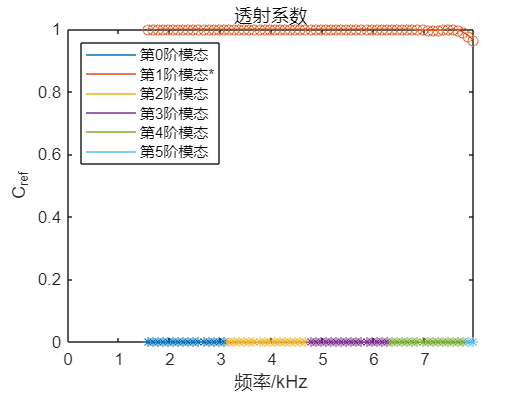

fig(2)=figure;
clear ct cti pic

legendText = [];
for ii = 1:incident.n
	tmp = cT{ii};
	nmode = length(tmp);
	for imode = 1:nmode
		ct(ii,imode) = tmp(imode);
	end
end

for imode = 1:nmode
	idx = find(ct(:,imode));
	iff = ff(idx);
	ict = ct(idx,imode);
	ffi = linspace(min(iff),max(iff),1000);
	cti(:,imode) = interp1(iff,ict,ffi,'spline');
	if imode == incident.mode
		pic(imode) = plot(ffi/kFactor,cti(:,imode),'SeriesIndex',imode);
		hold on
		plot(iff/kFactor,ict(:),'o','SeriesIndex',imode)
		legendText = [legendText;convertCharsToStrings(['第', num2str(imode-1), '阶模态*'])];
	else
		pic(imode) = plot(ffi/kFactor,cti(:,imode),'SeriesIndex',imode);
		hold on
		plot(iff/kFactor,ict(:),'*','SeriesIndex',imode)
		legendText = [legendText;convertCharsToStrings(['第', num2str(imode-1), '阶模态'])];
	end
end
hold off


xlim([0 wd]);
ylim([0 1])
% xticks(0:50:f/kFactor)
xlabel('频率/kHz')
ylabel('C_{ref}')
legend(pic,legendText,'Location','northwest')
% legend('1阶透射系数','','2阶透射系数','','3阶透射系数','','Location','northeastoutside')
title('透射系数')

反射系数

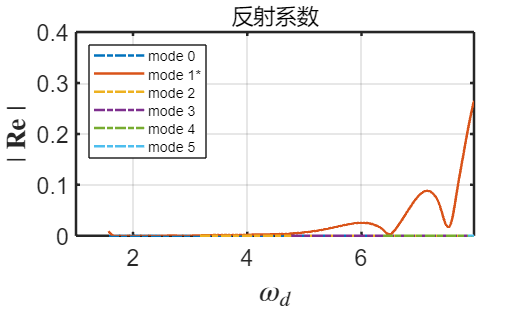

fig1 = figure();
fig1.Position = [488.2,176.2,810.4,484];
clear cr cri pic
cr = zeros(incident.n,nmode);
legendText = [];
for ii = 1:incident.n
	tmp = cR{ii};
	nmode = length(tmp);
	for imode = 1:nmode
		cr(ii,imode) = tmp(imode);
	end
end


for imode = 1:nmode
	idx = find(cr(:,imode));
	iff = ff(idx);
	ict = cr(idx,imode);
	ffi = linspace(min(iff),max(iff),1000);
	cri(:,imode) = interp1(iff,ict,ffi,'spline');
	if imode == incident.mode
		pic(imode) = plot(ffi/kFactor,cri(:,imode),'SeriesIndex',imode,LineWidth=1.5);
		hold on
% 		plot(iff/kFactor,ict(:),'o','SeriesIndex',imode)
		legendText = [legendText;convertCharsToStrings(['mode ', num2str(imode-1), '*'])];
	else
		pic(imode) = plot(ffi/kFactor,cri(:,imode),'SeriesIndex',imode,'LineStyle','-.',LineWidth=1.5);
		hold on
% 		plot(iff/kFactor,ict(:),'*','SeriesIndex',imode)
		legendText = [legendText;convertCharsToStrings(['mode ', num2str(imode-1)])];
	end
end
hold off
grid on

xlim([1,wd]);	ylim([0 0.4])

xlabel("$$\omega_d$$",Interpreter='latex')
ylabel("$$\mid\textbf{Re}\mid$$",Interpreter='latex',FontWeight='bold')
title("absolute value of transmission coefficient",FontSize=13)
a1 = gca;

a1.XAxis.LineWidth = 1.5;
a1.YAxis.LineWidth = 1.5;
a1.XAxis.FontSize = 14;
a1.YAxis.FontSize = 14;

a1.XLabel.FontSize = 18;
a1.YLabel.FontSize = 16;

% xlabel('\omegab/CT')
% ylabel('C_{ref}')
legend(pic,legendText,'Location','northwest')
% legend('1阶透射系数','','2阶透射系数','','3阶透射系数','','Location','northeastoutside')
title('反射系数')


error("程序已完成，下面是保存/加载fig")

程序已完成，下面是保存/加载fig

保存fig

savefig(fig,['E:\MyProject\matlab\MATLAB Drive\DtN-FEM3\result\coefficients\' ...
	'pipe_m5.fig'])

读取fig

openfig(['E:\MyProject\matlab\MATLAB Drive\DtN-FEM3\result\coefficients\' ...
	'pipe_m5.fig'],'visible')
